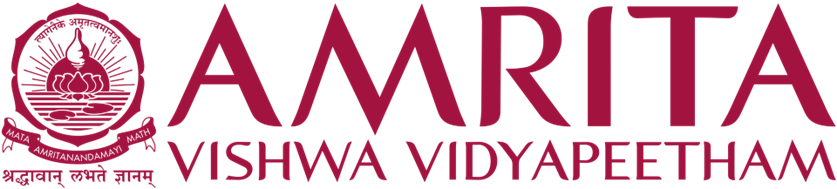

`22MAT230     MATHEMATICS  FOR  COMPUTING 4`

***Batch : AIE -C***

***Team 7***

-------------------------------------------------------------------

**G Prajwal Priyadarshan  -  CB.SC.U4AIE24214**

**Kabilan K               -  CB.SC.U4AIE24224**

**Kishore B                         -  CB.SC.U4AIE24227**

**Rahul L S                          - CB.SC.U4AIE24248**

-------------------------------------------------------------------

# **LLM Guided Regularization of Pseudoinverse for Ill-Posed Signal Reconstruction**

# **Introduction**

Many real-world systems do not allow direct observation of  the true signal. Instead we observe corrupted measurements.

This leads to an inverse problem of the form:

                         
$$y_{\delta \;\;=\;\;\;\textrm{Ax}+\eta }$$


where

A : forward operator (system matrix)

x : true signal

$y_{\delta }$ : observed measurement

η : noise

Recovering x from noisy measurements y is difficult because many inverse problems are ill-posed and highly sensitive to noise.

Small perturbations in measurements can produce extremely large errors in the reconstructed signal.

To address this instability we study regularization methods such as:

- Pseudoinverse (baseline)

- Truncated SVD (TSVD)

- Tikhonov Regularization

- Non-Stationary Iterated Tikhonov (NSIT)

- Fast NSIT (FNIST)

In this project we further introduce an LLM-guided parameter selection strategy to automatically recommend optimal regularization parameters.

# **Problem Statement**

In this project, we study the reconstruction of an unknown signal from noisy measurements. The inverse problem is modeled as

                                                        $\mathrm{Ax}=y_{\delta }$�

where

- $A\;$is the forward operator (system matrix),

- $x\;$ is the unknown signal to be reconstructed,

- $y_{\delta }$� represents the measured data.

In practice, the measured data contains noise and can be written as 

                                                         
$$y_{\delta } =y+\eta$$


where  $y\;$is the exact noise-free data and η represents measurement noise.

The noise level is assumed to satisfy   $\parallel \eta \parallel \le \delta$

where $\delta$ denotes an upper bound on the magnitude of the noise present in the measurements. 

The objective of the inverse problem is to estimate the unknown signal $x$ from the noisy observations $y_{\delta }$ However, when the operator  $A\;$is ill-conditioned, direct inversion becomes unstable, making regularization methods necessary for stable reconstruction.

# **What Are ill Posed Inverse Problems?**

A problem $\mathrm{Ax}=b$ is*** WELL POSED*** if:

1) Solution exists. 

2) Solution is unique. 

3) Solution depends continuously on the input data. 

If any of these conditions are violated, the problem is called** ill-posed.**

# **Well Posed vs ill Posed Problems**

We construct two matrices:

- a **full-rank random matrix** representing a well-conditioned system

- a **rank-deficient matrix** representing an ill-posed system.

The stability of each system is then analyzed using **Singular Value Decomposition (SVD)** and the **condition number**.

## 1) Full Rank Matrix 

**A full rank Matrix **has all singular values are non-zero.

For a well-conditioned matrix, the smallest singular value is not close to zero. 

This leads to 

- **moderate condition number** 

- stable inversion.

clc, clearvars
n = 100;
A1 = randn(n);              % Random Full rank matrix

[U1, S1, V1] = svd(A1);
singular_vals_A1 = diag(S1);

% Condition number
cond_A1 = cond(A1);
disp('Condtion number of Well Posed Matrix')

Condtion number of Well Posed Matrix


disp(cond_A1)

   5.3544e+03



## 2) ill Posed Matrix

To simulate an ill-posed system, a **rank-deficient operator** is constructed.

- Random orthogonal matrices $U\;$and  $V$ are generated using SVD.

- A singular value vector is defined as


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s=\left\lbrack \sigma 1,\sigma 2,\ldotp \ldotp \ldotp ,\sigma r,0,\ldotp \ldotp \ldotp ,0\right\rbrack$$


where only the first  $r\;$ singular values are non-zero.

- The matrix is constructed as

                                           
$$A=U\Sigma V^T$$


where  $\Sigma$  contains the predefined singular values.

**Interpretation**

Because several singular values are exactly zero, the matrix loses rank and becomes **rank deficient**.

This leads to:

- a very large condition number

- unstable inversion

- strong sensitivity to noise.

function A = rankdeficient_operator(n, r)
    [U,~,V] = svd(randn(n), 'econ');   % random orthogonal matrices
    s = [linspace(1,0.1,r) zeros(1,n-r)];   % r non-zero singular values
    A = U * diag(s) * V';   % construct matrix
end
A2 = rank_deficient_operator(n, 12);
[U2, S2, V2] = svd(A2);
singular_vals_A2 = diag(S2);

Condition number of Ill posed Matrix:


   3.1797e+18



% Condition number
cond_A2 = cond(A2);

disp('Condition number of Ill posed Matrix:')
disp(cond_A2)

### Singular Value Spectrum

The singular values of Well-Conditioned and ill-posed Matrices are plotted on a **logarithmic scale** using a semilog plot.

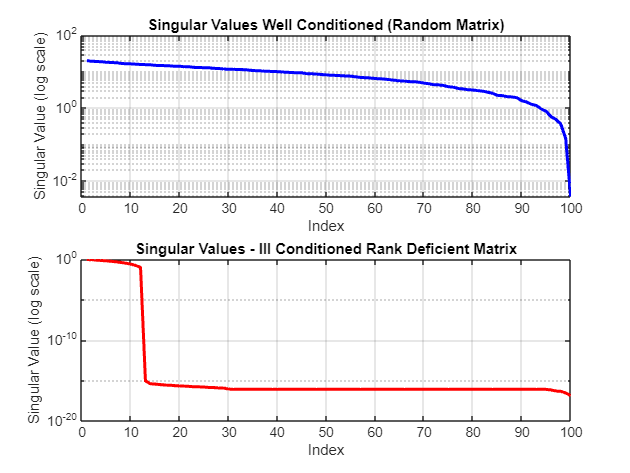

figure;
subplot(2,1,1)
semilogy(singular_vals_A1, 'b', 'LineWidth', 2);
grid on;
title('Singular Values Well Conditioned (Random Matrix)');
xlabel('Index');
ylabel('Singular Value (log scale)');

subplot(2,1,2)
semilogy(singular_vals_A2, 'r', 'LineWidth', 2);
grid on;
title('Singular Values - Ill Conditioned Rank Deficient Matrix');

xlabel('Index');
ylabel('Singular Value (log scale)');

- The rapid decay of singular values causes instability in inverse problems. When attempting to compute the inverse solution, small singular values amplify noise present in the data.

For the random full-rank matrix:

- Singular values remain relatively well distributed.

- None of the singular values approach zero.

- The spectrum does not decay rapidly.

This indicates that the matrix is **well-conditioned**, and inversion is numerically stable.

For the rank-deficient matrix:

- Singular values decay rapidly.

- Several singular values are exactly zero.

- The spectrum drops sharply.

This behavior indicates **ill-conditioning** and loss of rank.

### Stability Check

Two vectors are considered:

- $\mathrm{b1}$ : the original data vector

- ${\mathrm{b1}}_{\mathrm{noisy}}$: a slightly perturbed version of the data

The noisy vector is generated by adding a very small random perturbation:

                                                 
$${\mathrm{b1}}_{\mathrm{noisy}} =\mathrm{b1}+\varepsilon$$


where    $\epsilon$  is a small noise term.

The linear system is then solved using both vectors for the two matrices:

                                                  
$$x=A^{-1} \mathrm{b1}$$


The difference between the resulting solutions is measured using the Euclidean norm:

                                                
$$\parallel x_{\mathrm{original}} -x_{\mathrm{noisy}} \parallel$$


Well-Conditioned Matrix

For the full-rank matrix  $A_1$:

- Small perturbations in the data produce **small changes in the solution**.

- The difference between the two solutions remains very small.

- This confirms that the system is **stable**.

**Ill-Conditioned Matrix**

For the rank-deficient matrix $A_2$�:

- Even a tiny perturbation in the data causes **large variations in the solution**.

- The difference between the two solutions becomes significantly larger.

- This indicates that the system is **highly unstable**.

b1 = randn(n,1);
b1_noisy = b1 + 1e-6*randn(n,1);

x1_original = A1 \ b1;
x1_noisy    = A1 \ b1_noisy;
difference_well = norm(x1_original - x1_noisy);

x2_original = A2 \ b1;

x2_noisy    = A2 \ b1_noisy;

difference_ill = norm(x2_original - x2_noisy);

disp('Difference for Well-Conditioned Matrix:')

Difference for Well-Conditioned Matrix:


disp(difference_well)

   5.6937e-05




disp('Difference for Ill-Conditioned Matrix:')

Difference for Ill-Conditioned Matrix:


disp(difference_ill)

   4.1918e+12



### Condition Number via Singular 

For a matrix $A$, the condition number is defined as

                                  
$$\kappa \left(A\right)=\frac{\sigma_{\max } }{\sigma_{\min } }\mathrm{ }$$


where

- $\sigma_{\max }$ is the largest singular value of $A$

- $\sigma_{\min }$ � is the smallest singular value of $A$

cond_manual_A1 = max(singular_vals_A1) / min(singular_vals_A1);
cond_manual_A2 = max(singular_vals_A2) / min(singular_vals_A2);

disp('Manual Condition Number (Random):')

Manual Condition Number (Random):


disp(cond_manual_A1)

   5.3544e+03




disp('Manual Condition Number (Hilbert):')

Manual Condition Number (Hilbert):


disp(cond_manual_A2)

   7.4082e+16



## Methodology

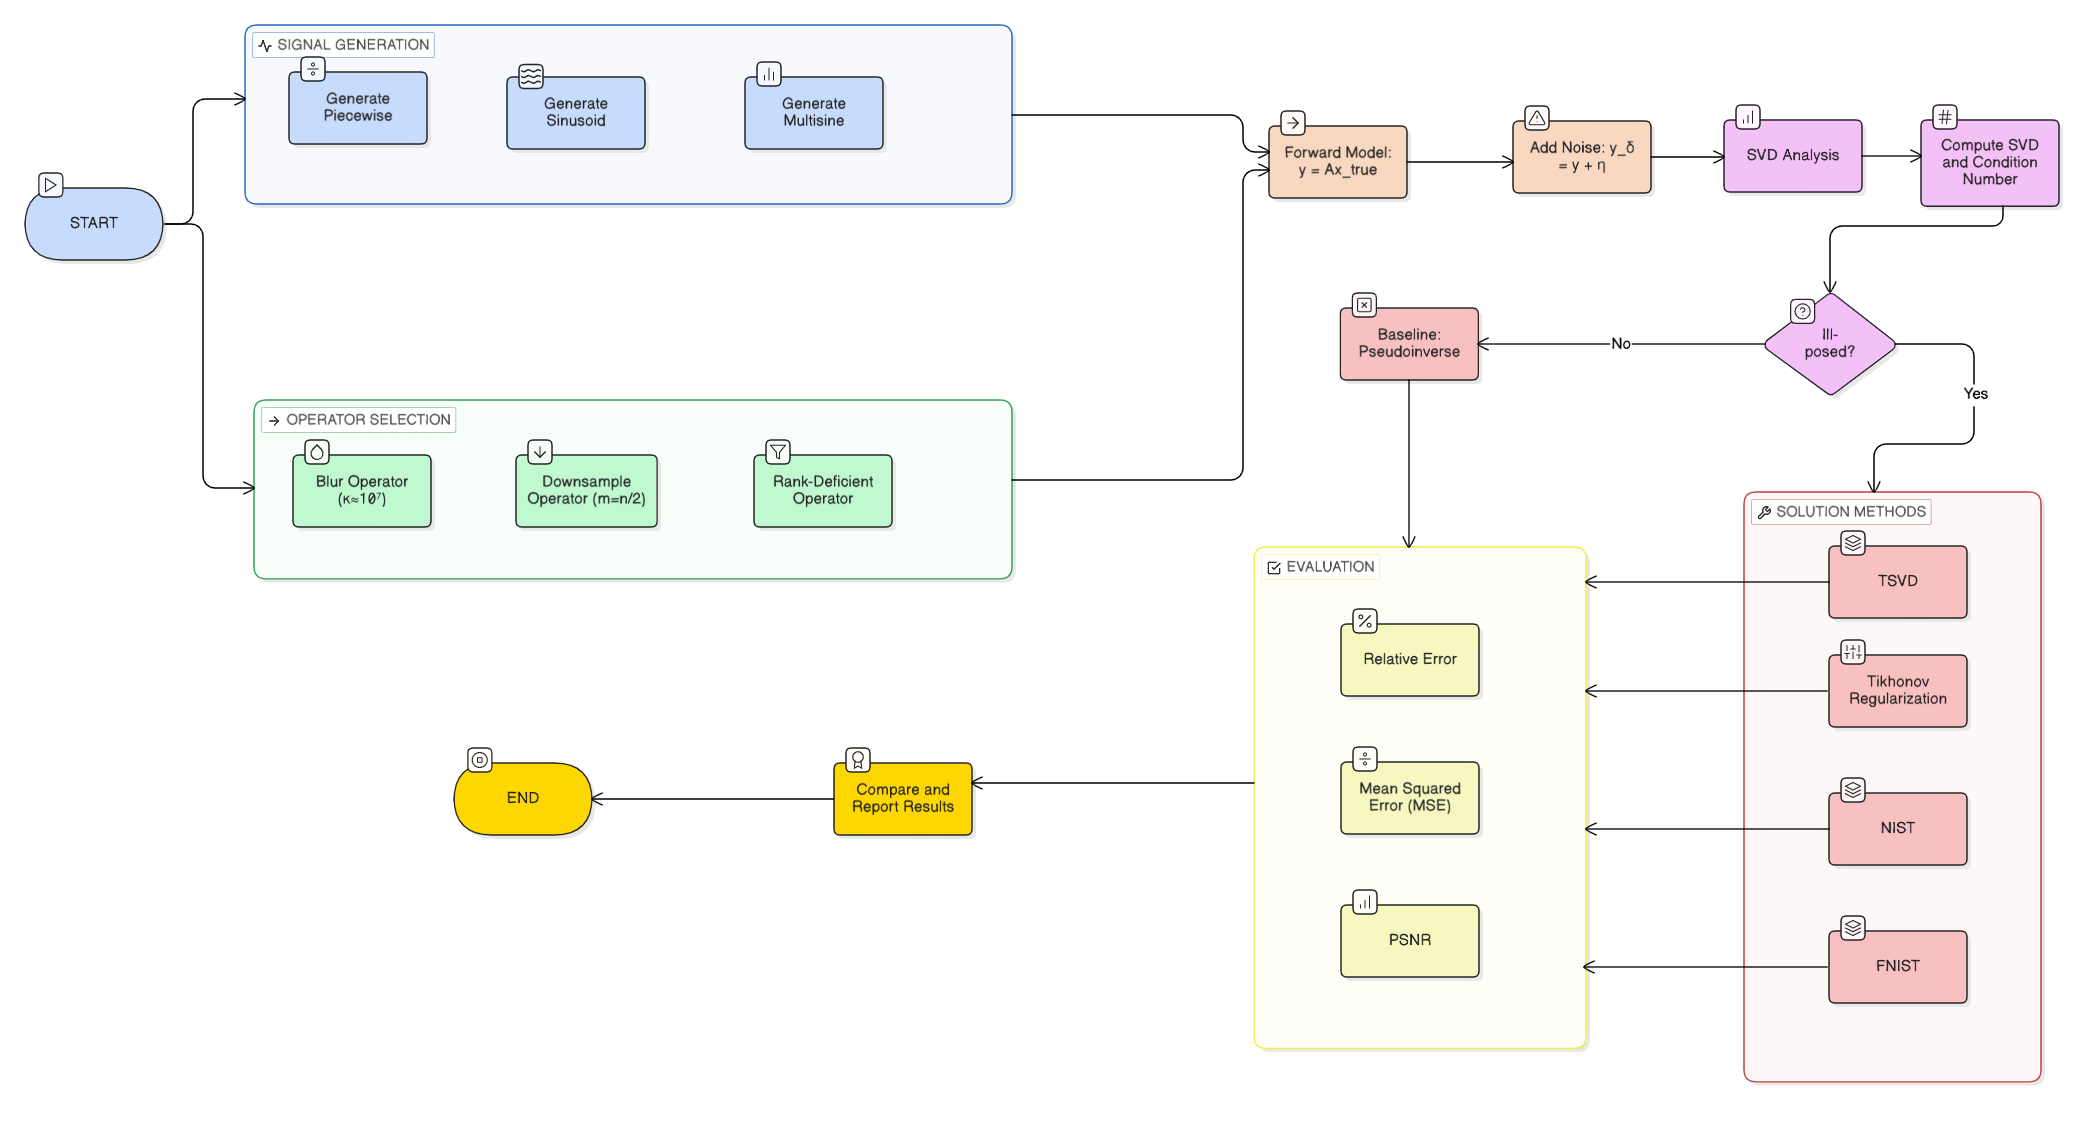

# **Signal Generation**

**Sinusoidal Signal**

The sinusoidal signal is defined as

                                                
$$y\left(t\right)=\mathrm{sin }\left(2\pi t\right)+0\ldotp 5\mathrm{sin }\left(6\pi t\right)$$


This represents a smooth periodic signal composed of two frequency components.

function y = sinusoid(t)
    y = sin(2*pi*t) + 0.5*sin(6*pi*t);
end

**Multisine Signal**

The multisine signal is constructed as the sum of multiple sinusoidal components

                                            
$$y\left(t\right)=\sum_{k=1}^K a_k \sin \left(2\pi f_k t\right)$$


where $f_k$ represents the frequencies and $a_k$ represents the amplitudes of the individual sine waves. This signal introduces more complex oscillatory behavior.

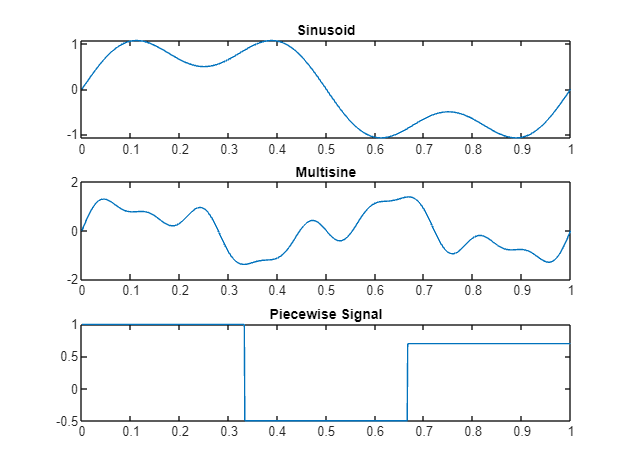

function y = multisine(t, freqs, amps)
    if nargin < 2
        freqs = [2 5 9];
    end
    if nargin < 3
        amps = [1.0 0.6 0.3];
    end


    y = zeros(size(t));
    for k = 1:length(freqs)
        y = y + amps(k) * sin(2*pi*freqs(k)*t);
    end
end

**Piecewise Signal**

The piecewise signal is defined as a signal with constant values over different intervals

                                       $y(t) =
\left\{
\begin{array}{ll}
1.0, & 0 \le t < \frac{1}{3} \\
-0.5, & \frac{1}{3} \le t < \frac{2}{3} \\
0.7, & \frac{2}{3} \le t \le 1
\end{array}
\right.$�

This signal contains abrupt transitions and discontinuities, making it useful for testing the ability of reconstruction methods to preserve sharp changes.

function y = piecewise_signal(t)
    y = zeros(size(t));
    N = length(t);
    thirds = floor(N/3);

    y(1:thirds) = 1.0;
    y(thirds+1:2*thirds) = -0.5;
    y(2*thirds+1:end) = 0.7;
end

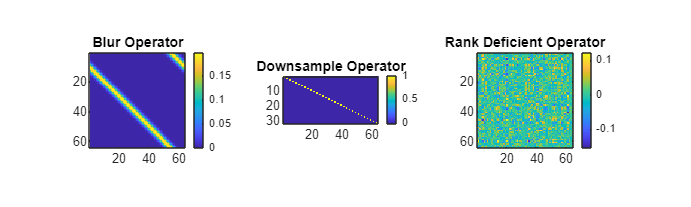

t = linspace(0, 1, 1000);

y1 = sinusoid(t);
y2 = multisine(t);
y3 = piecewise_signal(t);


figure;
subplot(3,1,1); plot(t, y1); title('Sinusoid');
subplot(3,1,2); plot(t, y2); title('Multisine');
subplot(3,1,3); plot(t, y3); title('Piecewise Signal');

# **Forward Models**

To simulate the measurement process in inverse problems, different **forward operators** are applied to the original signal. These operators model how the true signal is transformed before it is observed.

The general forward model is given by

                                                  
$$y=\mathrm{Ax}$$


where  $A\;$represents the forward operator, $x$ is the original signal, and $y$ is the observed measurement.

## Gaussian Blur Operator

The Gaussian blur operator models a **smoothing process**, where the signal is convolved with a Gaussian kernel. The kernel determines how neighboring signal values contribute to the blurred measurement.

                                                    
$$k(i) = \frac{1}{Z} \exp\left(-\frac{i^{2}}{2\sigma^{2}}\right)$$


where

- $k\left(i\right)$ - value of the Gaussian kernel at position iii

- $\sigma$ - standard deviation controlling the amount of blur

- $Z$ - normalization constant ensuring the kernel sums to 1.

The blurred measurement is obtained by applying the blur operator

                                                  
$$y = A_{\text{blur}} x$$


where

- $A_{\mathrm{blur}}$� -  matrix representation of the Gaussian blur operator

- $x$ - original signal

- $y$ - blurred measurement.

This operator suppresses high-frequency components of the signal.

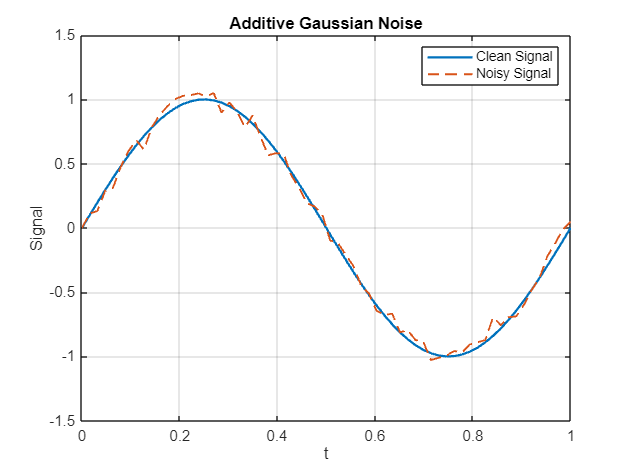

function A = blur_operator(n, sigma, kernel_radius)
% BLUR_OPERATOR  Circulant Gaussian blur matrix

    if nargin < 3
        kernel_radius = 10;
    end

    ksize = 2 * kernel_radius + 1;
    k = gaussian_kernel(ksize, sigma);

    A = zeros(n, n);

    for i = 1:n
        for j = 1:n

            shift = mod(i - j, n);
            if shift < ksize
                A(i, j) = k(shift + 1);
            end
        end
    end
end
function k = gaussian_kernel(sz, sigma) % GAUSSIAN_KERNEL 1D Gaussian kernel 
    idx = -(floor(sz/2)) : floor(sz/2); 
    k = exp(-0.5 * (idx / sigma).^2); 
    k = k / sum(k); 
end

## Downsampling Operator

The downsampling operator simulates the situation where measurements are taken at a **lower resolution**. Instead of observing every element of the signal, only selected samples are recorded.

Each measurement is obtained as

##                                                           
$$y_i = x_{(i-1)f + 1}
$$


where

- $y_i \;\;\;\;:\;$ith measurement value

- $x\left(j\right)$  : value of the original signal at index $j$

- $f\;$downsampling factor determining the sampling interval.

In matrix form the model becomes

##                                                         
$$y = A_{\text{down}} x
$$


where

- $A_{\mathrm{down}\;}$  : downsampling operator matrix

- $x$   :  original signal

- $y$ :  reduced measurement vector.

This operator causes **loss of information**, making the inverse problem more difficult.

function A = downsample_operator(n, factor)
% DOWNSAMPLE_OPERATOR  Downsampling matrix

    if nargin < 2
        factor = 2;
    end

    m = floor(n / factor);
    A = zeros(m, n);

    for i = 1:m
        A(i, (i-1)*factor + 1) = 1.0;
    end
end

## Rank-Deficient Operator

A rank-deficient operator is constructed using the **Singular Value Decomposition (SVD)** to simulate an ill-posed system.

**Equation**

                                                                    
$$A = U \Sigma V^{T}

$$


where

- $U\;$ : orthogonal matrix containing left singular vectors

- $V\;$: orthogonal matrix containing right singular vectors

- $\Sigma$  : diagonal matrix containing the singular values.

The singular value matrix is defined as

**Equation**


$$\Sigma =
\left[
\matrix{
\sigma_{1} & 0 & 0 & \cdots \cr
0 & \sigma_{2} & 0 & \cdots \cr
0 & 0 & \ddots & 0 \cr
0 & 0 & 0 & \sigma_{r}
}
\right]$$


where

- $\sigma 1,\sigma 2,\ldots,\sigma r$ are  non-zero singular values

- remaining entries are zero.

Since only the first $r\;$singular values are non-zero, the matrix has reduced rank


$$\text{rank}(A) = r < n$$


where

- $r$ : rank of the matrix

- $n$ : dimension of the matrix.

This rank deficiency makes the system **ill-posed**, because certain components of the signal cannot be recovered.

function A = rank_deficient_operator(n, r)

Forward operator matrix A: shape = 100 x 100


    [U,~,V] = svd(randn(n), 'econ');   % random orthogonal matrices

Condition number (using diagnostics): κ(A) = 1.94e+06


    s = [linspace(1,0.1,r) zeros(1,n-r)];   % r non-zero singular values
    A = U * diag(s) * V';   % construct matrix
end

## Visuzalization Of Forward Operators

n = 100;

A_blur = blur_operator(n, 2.0);
A_down = downsample_operator(n, 2);
A_rank = rankdeficient_operator(n, 12);

figure('Position',[100 100 1000 300])
subplot(1,3,1); imagesc(A_blur); axis image;
title('Blur Operator'); colorbar;

subplot(1,3,2); imagesc(A_down); axis image;
title('Downsample Operator'); colorbar;

subplot(1,3,3); imagesc(A_rank); axis image;
title('Rank Deficient Operator'); colorbar;

### Noise Models

n = 100;
t = linspace(0,1,n)';
x = sin(2*pi*t);

sigma = 0.05;   % noise level

[y_noisy, noise] = add_gaussian_noise(x, sigma);

Relative Error: 27107.9725


MSE: 454683593.547804


figure
plot(t,x,'LineWidth',1.5)
hold on
plot(t,y_noisy,'--','LineWidth',1.2)

legend('Clean Signal','Noisy Signal')
title('Additive Gaussian Noise')
xlabel('t')
ylabel('Signal')
grid on

function [y_noisy, noise] = add_gaussian_noise(y, sigma, rng)

    if nargin < 3 || isempty(rng)
        noise = sigma * randn(size(y));
    else
        noise = sigma * randn(rng, size(y));
    end

    y_noisy = y + noise;

end

## **Reconstruction Methods**

n = 100;              % signal length
noise_level = 0.08;   % noise standard deviation
blur_sigma = 2.5;     % blur kernel width

% Generate true signal
t = linspace(0,1,n);


TSVD Parameter Sweep Results:


x_true = sin(2*pi*t)' + 0.5*sin(6*pi*t)'; 

k range: 1 to 99


Optimal k: 7


% Create forward operator (blur matrix)

Optimal MSE: 0.000948


A = blur_operator(n, blur_sigma, 10);

Optimal Relative Error: 0.039142



% Compute condition number
cond_num = cond(A);

fprintf('Forward operator matrix A: shape = %d x %d\n', size(A,1), size(A,2));
fprintf('Condition number (using diagnostics): κ(A) = %.2e\n', cond_num);

% Forward model
y_clean = A * x_true;

% Add Gaussian noise
[y_noisy, noise_vec] = add_gaussian_noise(y_clean, noise_level);

%From this we will use A and y_noisy for reconstruction

### PINV 

function x = pseudoinverse_reconstruct(A, y_noisy)
    % Reconstruct signal using pseudoinverse
    % Inputs:
    % A - Forward operator matrix (n x m)
    % y_noisy - Noisy measurement vector (n x 1)
    
    % Output:
    % x - Reconstructed signal (m x 1)
        
    x = pinv(A) * y_noisy;
end

% Reconstruct
x_pinv = pseudoinverse_reconstruct(A, y_noisy);

% Compute reconstruction errors
mse_val = mse_error(x_true, x_pinv);
rel_error = relative_error(x_true, x_pinv);

fprintf('Relative Error: %.4f\n', rel_error);
fprintf('MSE: %.6f\n', mse_val);


### **TSVD**

function x = tsvd_reconstruct(A, y, k)
    % TSVD_RECONSTRUCT  Truncated SVD reconstruction
    % Inputs:
    % A - Forward operator matrix
    % y - noisy observation
    % k - truncation parameter
    % Output:

Tikhonov Parameter Sweep Results:


    % x - reconstructed signal

Lambda range: 1.00e-06 to 1.00e+02


Optimal lambda: 7.906043e-02


    [U,S,V] = svd(A,'econ');

Optimal MSE: 0.008548


Optimal Relative Error: 0.117539


    % Truncate SVD components
    Uk = U(:,1:k);
    Sk = S(1:k,1:k);
    Vk = V(:,1:k);
    
    % TSVD solution
    x = Vk * (Sk \ (Uk' * y));
end

% Parameter sweep for TSVD
step = max(1, floor(n/50));
ks = 1:step:n-1;

num_k = length(ks);

mse_vals = zeros(num_k,1);
rel_vals = zeros(num_k,1);

x_store = cell(num_k,1);

for i = 1:num_k
    

NSIT stopped at iteration 5


    k = ks(i);

Mean Squared Error = 0.003386


Relative Error = 0.073978


    % TSVD reconstruction
    x_tsvd = tsvd_reconstruct(A, y_noisy, k);

    % Metrics
    mse_vals(i) = mse_error(x_true, x_tsvd);
    rel_vals(i) = relative_error(x_true, x_tsvd);

    x_store{i} = x_tsvd;

end

% Find optimal k
[best_mse_tsvd, best_idx] = min(mse_vals);
best_k = ks(best_idx);
best_rel_tsvd = rel_vals(best_idx);
x_best_tsvd = x_store{best_idx};

fprintf('\nTSVD Parameter Sweep Results:\n');
fprintf('k range: %d to %d\n', ks(1), ks(end));
fprintf('Optimal k: %d\n', best_k);
fprintf('Optimal MSE: %.6f\n', best_mse_tsvd);
fprintf('Optimal Relative Error: %.6f\n', best_rel_tsvd);

### Tikhonov

function x_tik = tikhonov_reconstruct(A, y, lambda)
% Tikhonov reconstruction
% Solves: min ||Ax - y||^2 + lambda ||x||^2

% Inputs:
% A - Forward operator matrix
% y - Observed noisy data
% lambda - Regularization parameter

% Output:
% x_tik - Reconstructed signal


FNIST Reconstruction Results:


Relative Error: 0.124670


[m, n] = size(A);

MSE: 0.009617



% Identity matrix
I = eye(n);

% Tikhonov solution
x_tik = (A' * A + lambda * I) \ (A' * y);
end

lambdas = logspace(-6,2,50);

mse_vals = zeros(length(lambdas),1);
rel_err_vals = zeros(length(lambdas),1);

x_results = cell(length(lambdas),1);

for i = 1:length(lambdas)

    lam = lambdas(i);

    % Reconstruction
    x_tik = tikhonov_reconstruct(A, y_noisy, lam);

    % Metrics
    mse_vals(i) = mse_error(x_true, x_tik);
    rel_err_vals(i) = relative_error(x_true, x_tik);

    x_results{i} = x_tik;

end

% Find optimal lambda
[best_mse_tikh, best_idx] = min(mse_vals);

best_lambda = lambdas(best_idx);
best_rel_tikh = rel_err_vals(best_idx);
x_best_tikh = x_results{best_idx};

fprintf('Tikhonov Parameter Sweep Results:\n');
fprintf('Lambda range: %.2e to %.2e\n', lambdas(1), lambdas(end));
fprintf('Optimal lambda: %.6e\n', best_lambda);
fprintf('Optimal MSE: %.6f\n', best_mse_tikh);
fprintf('Optimal Relative Error: %.6f\n', best_rel_tikh);

### **NIST**

function [x_rec, residuals, rel_errors, stop_iter] = nsit_morozov(A, y, x_true, delta, q, tau, max_iter)

% NSIT reconstruction using Morozov discrepancy principle
% A        : forward operator
% y        : noisy measurements
% x_true   : true signal (only for error evaluation)
% delta    : noise level
% q        : geometric decay factor (0<q<1)
% tau      : Morozov safety factor
% max_iter : maximum iterations

[m,n] = size(A);

x = zeros(n,1);

At = A';
AtA = At*A;

% Proper scaling of alpha
alpha0 = norm(A)^2;

residuals = zeros(max_iter,1);
rel_errors = zeros(max_iter,1);

for k = 1:max_iter

    % Geometric alpha schedule
    alpha = alpha0 * q^(k-1);

    % Compute residual
    r = y - A*x;

    % NSIT correction step
    correction = (AtA + alpha*eye(n)) \ (At*r);

    % Update solution

    x = x + correction;

Reconstruction Method Comparison


    % Residual norm
    residuals(k) = norm(y - A*x);

    % Relative error (for evaluation)
    rel_errors(k) = relative_error(x_true, x);

Pseudoinverse | Rel Error: 27107.972469 | MSE: 454683593.547804
TSVD         | Rel Error: 0.039142 | MSE: 0.000948
Tikhonov     | Rel Error: 0.117539 | MSE: 0.008548
NSIT         | Rel Error: 0.073978 | MSE: 0.003386
FNIST        | Rel Error: 0.065126 | MSE: 0.002624



    % Morozov stopping rule
    if residuals(k) <= tau * delta
        break
    end

end

x_rec = x;
stop_iter = k;

residuals = residuals(1:k);
rel_errors = rel_errors(1:k);

end

max_iter = 200;
q = 0.9;
tau = 1.01;

delta = norm(noise_vec);

[x_nsit, residuals, errors, stop_iter] = nsit_morozov(A, y_noisy, x_true, delta, q, tau, max_iter);

nsit_best_mse = mse_error(x_true,x_nsit);
nsit_best_rel = errors(end);

fprintf('NSIT stopped at iteration %d\n', stop_iter);
fprintf('Mean Squared Error = %.6f\n', nsit_best_mse);
fprintf('Relative Error = %.6f\n', nsit_best_rel);


### **FNIST**

function x_rec = fnist_reconstruction(A, y, alpha0, q, max_iter)
    [~,n] = size(A);
    x = zeros(n,1);
    At = A';
    AtA = At*A;
    
    for k = 1:max_iter
        alpha = alpha0 * q^(k-1);
        r = y - A*x;
        % First correction
        F1 = (AtA + alpha*eye(n)) \ (At*r);
        % Second correction (correct form)
        temp = (AtA + alpha^2*eye(n)) \ (At*r);
        F2 = alpha * ((AtA + alpha*eye(n)) \ temp);
        % Stable update
        x = x + 0.7*F1 + 0.3*F2;
    end
    x_rec = x;
end

alpha0 = 1;
q = 0.9;
max_iter = 10;

x_fnist = fnist_reconstruction(A, y_noisy, alpha0, q, max_iter);

% metrics
mse_val = mse_error(x_true, x_fnist);
rel_error = relative_error(x_true, x_fnist);

fprintf('\nFNIST Reconstruction Results:\n');
fprintf('Relative Error: %.6f\n', rel_error);
fprintf('MSE: %.6f\n', mse_val);

alpha_vals = logspace(-2,2,25);   % alpha0 values
q_vals = 0.85:0.01:0.99;           % decay factors
iter_vals = 5:30;                 % iterations

best_mse = inf;
best_rel = inf;
best_alpha = 0;
best_q = 0;
best_iter = 0;
best_x = zeros(size(x_true));

for a = 1:length(alpha_vals)
    for b = 1:length(q_vals)
        for c = 1:length(iter_vals)

            alpha0 = alpha_vals(a);
            q = q_vals(b);
            max_iter = iter_vals(c);

            x_fnist = fnist_reconstruction(A, y_noisy, alpha0, q, max_iter);

            mse_val = mse_error(x_true, x_fnist);
            rel_err = relative_error(x_true, x_fnist);

            if mse_val < best_mse
                best_mse = mse_val;
                best_rel = rel_err;
                best_alpha = alpha0;
                best_q = q;
                best_iter = max_iter;
                best_x = x_fnist;
            end
        end
    end
end

best_mse_fnist = best_mse;
best_rel_fnist = best_rel;
x_fnist_best = best_x;

fprintf("\nOptimal FNIST Parameters:\n");
fprintf("alpha0 = %.4f\n", best_alpha);
fprintf("q = %.3f\n", best_q);
fprintf("iterations = %d\n", best_iter);
fprintf("Best MSE = %.6f\n", best_mse_fnist);
fprintf("Best Relative Error = %.6f\n", best_rel_fnist);

### Evaluation Metrics

function err = relative_error(x_true, x_rec)
err = norm(x_true - x_rec) / norm(x_true);
end

function mse = mse_error(x_true, x_rec)
mse = mean((x_true - x_rec).^2);
end

## **Model Comparison**

methods = {'Pseudoinverse','TSVD','Tikhonov','NSIT','FNIST'};

rel_errors = [

LLM Suggested Parameters:


    relative_error(x_true, x_pinv);

        TSVD: [1×1 struct]
    Tikhonov: [1×1 struct]
        NSIT: [1×1 struct]
       FNIST: [1×1 struct]



    best_rel_tsvd;
    best_rel_tikh;
    nsit_best_rel;
    best_rel_fnist
];

mses = [
    mse_error(x_true, x_pinv);
    best_mse_tsvd;
    best_mse_tikh;
    nsit_best_mse;
    best_mse_fnist
];

fprintf('\n=====================================\n');
fprintf('Reconstruction Method Comparison\n');
fprintf('=====================================\n');

for i = 1:length(methods)
    fprintf('%-12s | Rel Error: %.6f | MSE: %.6f\n',...
        methods{i}, rel_errors(i), mses(i));
end

## **LLM Parameter selection**

% BUILD PROMPT FOR LLM

prompt = "";

prompt = prompt + "You are an expert in numerical linear algebra and inverse problems." + newline;
prompt = prompt + "Your task is to recommend optimal regularization parameters for solving an ill-posed inverse problem." + newline;
prompt = prompt + "We are solving the reconstruction problem Ax = y where A is ill-conditioned and the measurements contain noise." + newline + newline;

prompt = prompt + "======================================" + newline;
prompt = prompt + "PROBLEM DESCRIPTION" + newline;
prompt = prompt + "======================================" + newline;

prompt = prompt + "Signal model:" + newline;
prompt = prompt + "- Signal type: multisine signal (sum of multiple sinusoids)" + newline;
prompt = prompt + "- Signal length: " + num2str(n) + newline;
prompt = prompt + "- Sampling interval: uniform in [0,1]" + newline + newline;

prompt = prompt + "Forward model:" + newline;
prompt = prompt + "- Operator type: Gaussian blur operator" + newline;
prompt = prompt + "- Blur sigma: " + num2str(blur_sigma) + newline;
prompt = prompt + "- Matrix size: " + num2str(size(A,1)) + " x " + num2str(size(A,2)) + newline;
prompt = prompt + "- Matrix rank: " + num2str(rank(A)) + newline;
prompt = prompt + "- Condition number: " + num2str(cond_num) + newline + newline;

prompt = prompt + "Noise model:" + newline;
prompt = prompt + "- Additive Gaussian noise" + newline;
prompt = prompt + "- Noise standard deviation: " + num2str(noise_level) + newline;
prompt = prompt + "- Noise norm: " + num2str(norm(noise_vec)) + newline + newline;


prompt = prompt + "======================================" + newline;
prompt = prompt + "CURRENT RECONSTRUCTION PERFORMANCE" + newline;
prompt = prompt + "======================================" + newline;

prompt = prompt + "Relative reconstruction errors:" + newline;
prompt = prompt + "- Pseudoinverse: " + num2str(rel_errors(1)) + newline;
prompt = prompt + "- TSVD: " + num2str(rel_errors(2)) + newline;
prompt = prompt + "- Tikhonov: " + num2str(rel_errors(3)) + newline;

prompt = prompt + "- NSIT: " + num2str(rel_errors(4)) + newline;
prompt = prompt + "- FNIST: " + num2str(rel_errors(5)) + newline + newline;

prompt = prompt + "Mean squared errors:" + newline;
prompt = prompt + "- Pseudoinverse: " + num2str(mses(1)) + newline;
prompt = prompt + "- TSVD: " + num2str(mses(2)) + newline;
prompt = prompt + "- Tikhonov: " + num2str(mses(3)) + newline;
prompt = prompt + "- NSIT: " + num2str(mses(4)) + newline;

prompt = prompt + "- FNIST: " + num2str(mses(5)) + newline + newline;

prompt = prompt + "======================================" + newline;
prompt = prompt + "OBJECTIVE" + newline;
prompt = prompt + "======================================" + newline;

prompt = prompt + "Select improved parameters that minimize reconstruction error and improve stability." + newline;
prompt = prompt + "Consider the ill-conditioning of A and the noise level when choosing parameters." + newline;

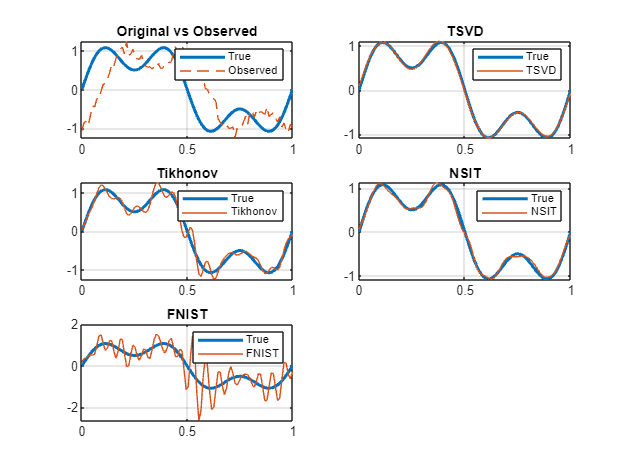

prompt = prompt + "Avoid parameter choices that cause instability or noise amplification." + newline + newline;


prompt = prompt + "======================================" + newline;
prompt = prompt + "ALGORITHMS TO TUNE" + newline;
prompt = prompt + "======================================" + newline;


----- Reconstruction Errors -----



prompt = prompt + "1) TSVD: choose truncation parameter k" + newline;

TSVD              : 0.039142


prompt = prompt + "2) Tikhonov: choose regularization parameter lambda" + newline;

TSVD + LLM        : 0.041002


prompt = prompt + "3) NSIT: choose q, iterations, delta, tau" + newline;
prompt = prompt + "4) FNIST: choose alpha0, q, iterations" + newline + newline;

Tikhonov          : 0.117539


Tikhonov + LLM    : 0.181156


prompt = prompt + "======================================" + newline;
prompt = prompt + "PARAMETER CONSTRAINTS" + newline;

NSIT              : 0.073978


prompt = prompt + "======================================" + newline;

NSIT + LLM        : 0.073509



prompt = prompt + "- k must be between 5 and 30" + newline;

FNIST             : 0.065126


prompt = prompt + "- lambda between 1e-6 and 1" + newline;

FNIST + LLM       : 0.700339


prompt = prompt + "- alpha0 between 0.001 and 0.5" + newline;
prompt = prompt + "- q between 0.5 and 0.95" + newline;
prompt = prompt + "- iterations between 10 and 60" + newline;
prompt = prompt + "- tau between 1.0 and 1.2" + newline;
prompt = prompt + "- delta should be close to the noise norm" + newline + newline;

prompt = prompt + "======================================" + newline;
prompt = prompt + "RESPONSE FORMAT" + newline;
prompt = prompt + "======================================" + newline;

prompt = prompt + "Return ONLY valid JSON with no explanation." + newline;
prompt = prompt + "Use exactly this structure:" + newline;

prompt = prompt + '{' + newline;
prompt = prompt + ' "TSVD": {' + newline;
prompt = prompt + '   "k": 12' + newline;
prompt = prompt + ' },' + newline;
prompt = prompt + ' "Tikhonov": {' + newline;
prompt = prompt + '   "lambda": 0.015' + newline;
prompt = prompt + ' },' + newline;
prompt = prompt + ' "NSIT": {' + newline;
prompt = prompt + '   "q": 0.92,' + newline;
prompt = prompt + '   "iterations": 15,' + newline;
prompt = prompt + '   "delta": 0.1,' + newline;
prompt = prompt + '   "tau": 1.02' + newline;
prompt = prompt + ' },' + newline;
prompt = prompt + ' "FNIST": {' + newline;
prompt = prompt + '   "alpha0": 0.15,' + newline;
prompt = prompt + '   "q": 0.9,' + newline;
prompt = prompt + '   "iterations": 18' + newline;
prompt = prompt + ' }' + newline;
prompt = prompt + '}';

api_key = "YOUR_API_KEY_HERE";
params = get_llm_parameters_gemini(prompt, api_key);
k_llm = params.TSVD.k;

lambda_llm = params.Tikhonov.lambda;

q_nsit = params.NSIT.q;
iter_nsit = params.NSIT.iterations;
delta_nsit = params.NSIT.delta;
tau_nsit = params.NSIT.tau;

alpha_fnist = params.FNIST.alpha0;
q_fnist = params.FNIST.q;
iter_fnist = params.FNIST.iterations;

disp("LLM Suggested Parameters:")
disp(params)

% RECONSTRUCTION WITH LLM PARAMETERS

% Tikhonov
x_rec_tikh_llm = tikhonov_reconstruct(A, y_noisy, lambda_llm);

% TSVD
x_rec_tsvd_llm = tsvd_reconstruct(A, y_noisy, k_llm);

% NSIT
[x_rec_nsit_llm,~,~,~] = nsit_morozov(A,y_noisy,x_true,delta_nsit,q_nsit,tau_nsit,iter_nsit);

% FNIST
x_rec_fnist_llm = fnist_reconstruction( ...
    A, ...
    y_noisy, ...
    alpha_fnist, ...
    q_fnist, ...
    iter_fnist );

% COMPUTE ERRORS
rel_tsvd_llm  = relative_error(x_true, x_rec_tsvd_llm);
rel_nsit_llm  = relative_error(x_true, x_rec_nsit_llm);
rel_fnist_llm = relative_error(x_true, x_rec_fnist_llm);
rel_tikh_llm = relative_error(x_true, x_rec_tikh_llm);

mse_tsvd_llm  = mse_error(x_true, x_rec_tsvd_llm);
mse_nsit_llm  = mse_error(x_true, x_rec_nsit_llm);
mse_fnist_llm = mse_error(x_true, x_rec_fnist_llm);
mse_tikh_llm = mse_error(x_true, x_rec_tikh_llm);

%% ==========================================================
%% VISUALIZATION
%% ==========================================================

figure

subplot(3,2,1)
plot(t',x_true,'LineWidth',2)
hold on
plot(t',y_noisy,'--')
title("Original vs Observed")
legend("True","Observed")
grid on

subplot(3,2,2)
plot(t',x_true,'LineWidth',2)
hold on
plot(t',x_rec_tsvd_llm)
title("TSVD")
legend("True","TSVD","TSVD + LLM")
grid on

subplot(3,2,3)
plot(t',x_true,'LineWidth',2)
hold on
plot(t',x_rec_tikh_llm)
title("Tikhonov")
legend("True","Tikhonov","Tikhonov + LLM")
grid on

subplot(3,2,4)
plot(t',x_true,'LineWidth',2)
hold on
plot(t',x_rec_nsit_llm)
title("NSIT")
legend("True","NSIT","NSIT + LLM")
grid on

subplot(3,2,5)
plot(t',x_true,'LineWidth',2)
hold on
plot(t',x_rec_fnist_llm)
title("FNIST")
legend("True","FNIST","FNIST + LLM")
grid on

% PRINT FINAL RESULTS

fprintf("\n----- Reconstruction Errors -----\n")

fprintf("TSVD              : %.6f\n",best_rel_tsvd)
fprintf("TSVD + LLM        : %.6f\n",rel_tsvd_llm)

fprintf("Tikhonov          : %.6f\n",best_rel_tikh)
fprintf("Tikhonov + LLM    : %.6f\n",rel_tikh_llm)

fprintf("NSIT              : %.6f\n",nsit_best_rel)
fprintf("NSIT + LLM        : %.6f\n",rel_nsit_llm)

fprintf("FNIST             : %.6f\n",best_rel_fnist)
fprintf("FNIST + LLM       : %.6f\n",rel_fnist_llm)

function params = get_llm_parameters_gemini(prompt, api_key)

url = "https://generativelanguage.googleapis.com/v1/models/gemini-2.5-flash:generateContent?key=" + api_key;
data = struct;
data.contents = {struct("parts",{struct("text",prompt)})};

options = weboptions( ...
    'MediaType','application/json', ...
    'ContentType','json', ...
    'Timeout',60);

response = webwrite(url,data,options);

text = response.candidates(1).content.parts(1).text;
% Remove markdown if present
text = erase(text,"```json");
text = erase(text,"```");

% Extract JSON safely
start_idx = find(text=='{',1,'first');
end_idx   = find(text=='}',1,'last');

json_text = text(start_idx:end_idx);

params = jsondecode(json_text);

end